# Question 12.4 Solution

clear all
close all

We now consider the solution of the convection equation in $1+1$ dimensions


$$\frac{\partial\phi}{\partial t}+U\frac{\partial\phi}{\partial x}=0$$


with periodic boundary conditions and the initial condition


$$\phi(x,0)=\sin(x)$$


To begin with, it's easiest to think of this as two separate problems, one where we discretise in space and another where we discretise in time. So for now, we'll consider an evenly spaced mesh with $N+1$ points given by the nodes $x_{i}$, $i=0,1,\ldots,N-1,N$.

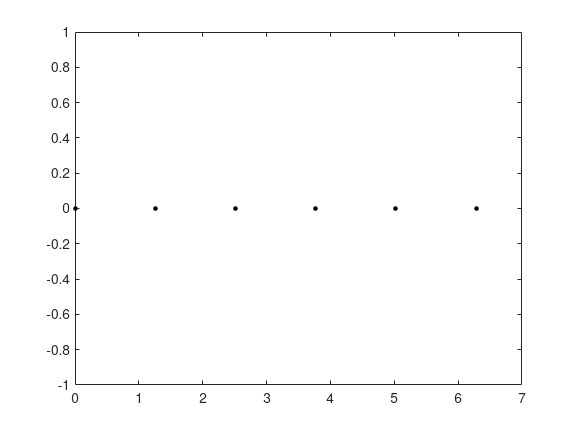

N = 5;
x = linspace(0,2*pi,N+1);
plot(x,zeros(size(x)),'k.','markersize',10)

Then, we may write the behaviour of the partial differential equation at the point $x_{i}$ as 


$$\frac{\partial\phi_{i}}{\partial t}+U\frac{\partial\phi_{i}}{\partial x}=0$$


For now, we'll completely ignore the temporal derivative by considering what happens at some time $t=t^{(n)}$. We can think of $\partial{\phi_{i}}/\partial t$ as another variable say $\dot{\phi}_{i}$ that only depends on $x$, so that this becomes a "boundary value problem"


$$\dot{\phi}_{i}+U\frac{\partial \phi_{i}}{\partial x}=0$$


Then discretising using the backwards difference formula


$$\frac{\partial \phi_{i}}{\partial x}=\frac{\phi_{i}-\phi_{i-1}}{\Delta x}$$


the convection equation becomes 


$$\dot{\phi_{i}}=-U\frac{\phi_{i}-\phi_{i-1}}{\Delta x}$$


whenever points are sequentially ordered, i.e. the interior nodes. Putting back the temporal derivative, we have


$$\frac{d\phi_{i}}{dt}=-U\frac{\phi_{i}-\phi_{i-1}}{\Delta x}$$


As a matrix product, this has the form


$$\frac{d\phi_{i}}{d t}=-\frac{U}{\Delta x}
\left[
\begin{array}{c}
-1 & 1
\end{array}
\right]
\left[
\begin{array}{c}
\phi_{i-1}\\
\phi_{i}
\end{array}
\right]$$


Now, for the boundary nodes, we can adapt the previous formula by extending the mesh to $x_{-1},x_{0},\ldots,x_{N},x_{N+1}$. Then using the periodic boundary conditions, we can loop the mesh back on itself so that $\phi_{-1}=\phi_{N}$ and $\phi_{0}=\phi_{N+1}$. Therefore, at the boundary nodes, we have 


$$\begin{array}{lcl}

\frac{d\phi_{0}}{dt}&=&-\frac{U}{\Delta x}(\phi_{0}-\phi_{N})\\
\frac{d\phi_{N}}{dt}&=&-\frac{U}{\Delta x}(\phi_{N}-\phi_{N-1})

\end{array}$$


And as a matrix product


$$\left[
\begin{array}{c}
\frac{d\phi_{0}}{dt}\\
\vdots\\
\frac{d\phi_{N}}{dt}
\end{array}
\right]
=
\frac{U}{\Delta x}
\left[
\begin{array}{c}
-1 & 0  & \cdots & 0 & 1\\
\vdots&&\ddots&&\vdots\\
                0 & \cdots & 0 & 1 & -1
\end{array}
\right]
\left[
\begin{array}{c}
\phi_{0}\\
\vdots\\
\phi_{N}
\end{array}
\right]$$


Putting everything together, we have


$$\left[
\begin{array}{c}
\frac{d\phi_{0}}{dt}\\
\vdots\\
\frac{d\phi_{N}}{dt}
\end{array}
\right]
=
\frac{U}{\Delta x}
\left[
\begin{array}{c}
-1 & 0  & \cdots & 0 & 1\\
                1& -1  &  & & \vdots \\
                \vdots & & \ddots &  \\
                0 &  &  1 & -1 & 0 \\
                0 & \cdots & 0 & 1 & -1
\end{array}
\right]
\left[
\begin{array}{c}
\phi_{0}\\
\phi_{1}\\
\vdots\\
\phi_{N-1}\\
\phi_{N}
\end{array}
\right]$$


Or more compactly,


$$\frac{d}{dt}\{\phi\}=\frac{U}{\Delta x}[C]\{\phi\}$$


What we can see here is that the process of approximating the spatial derivatives using a finite difference approximation gives us a set of $N+1$ ordinary differential equations to solve.

To solve this we can then apply a time stepping scheme, for simplicity we'll consider the explicit Euler method, which approximates a system of differential equations 


$$\frac{d}{dt}\{\phi\}=f(\{\phi\})$$


as 


$$\{\phi\}^{(n+1)}=\{\phi\}^{(n)}+\Delta t f(\{\phi\}^{(n)})$$


So applying this to the previous system, we have


$$\{\phi\}^{(n+1)}=\{\phi\}^{(n)}+\frac{U\Delta t}{\Delta x}[C]\{\phi\}^{(n)}$$


To code this up, we can follow a similar process as our discretisation, first we construct the convection matrix. To do this we can loop through each row of the matrix $[C]$ and place in the stencil $[1 -1]$.

N = 1000;
dx = (2*pi-0)/(N-1);
x = linspace(0,2*pi,N)';
C = zeros(N,N);

for i=1:N
    if i==1
        C(1,1) = -1;
        C(1,end) = 1;
    else
        C(i,i-1:i) = [1,-1];
    end
end


Then the time stepping may be done using using a second loop to implement the iterative formula 


$$\{\phi\}^{(n+1)}=\{\phi\}^{(n)}+\frac{U\Delta t}{\Delta x}[C]\{\phi\}^{(n)}$$


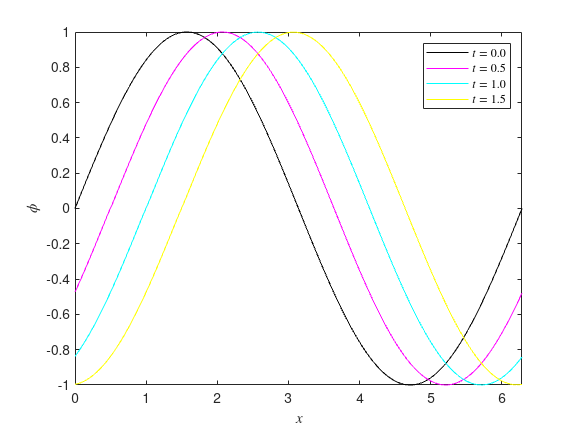

Nt = 1000;
dt = 0.005;
U = 1;
phi = sin(x);

figure(101)

phiout = zeros(N,3);

for n=1:Nt
    phi = phi+(U*dt/dx)*C*phi;

    if mod(n,100)==0 && n<=300
        phiout(:,n/100) = phi;
    end
end

plot(x,sin(x),'k-')
hold on
plot(x,phiout(:,1),'m-')
plot(x,phiout(:,2),'c-')
plot(x,phiout(:,3),'y-')
hold off
xlim([0,2*pi])
xlabel('$x$','interpreter','latex')
ylabel('$\phi$','interpreter','latex')
legend('$t=0.0$','$t=0.5$','$t=1.0$','$t=1.5$','interpreter','latex')

which shows the sine curve moving in the positive direction.